Initialization

cd('C:\Users\andpo\GitHub_projects\UOW_Projects\UOW_Computer_Lab\ROB\ARTE')
init_lib
%robot = load_robot('ABB','IRB140')
%teach

robot.DH.theta = '[q(1) q(2)-pi/2 q(3) q(4) q(5) q(6)+pi]';
robot.DH.d     = '[0.352 0 0 0.38 0 0.065]';
robot.DH.a     = '[0.07 0.36 0 0 0 0]';
robot.DH.alpha = '[-pi/2 0 -pi/2 pi/2 -pi/2 0]';

q = [0 0 0 0 0 0];
Theta =eval(robot.DH.theta)

Theta =          0   -1.5708         0         0         0    3.1416


d = eval(robot.DH.d)

d =     0.3520         0         0    0.3800         0    0.0650


a = eval(robot.DH.a)

a =     0.0700    0.3600         0         0         0         0


alpha = eval(robot.DH.alpha)

alpha =    -1.5708         0   -1.5708    1.5708   -1.5708         0


% For the first link
T01 = dh(Theta(1),d(1),a(1),alpha(1))

T01 =     1.0000         0         0    0.0700
         0    0.0000    1.0000         0
         0   -1.0000    0.0000    0.3520
         0         0         0    1.0000


% Another method
T01 = dh(robot,q,1);

% And the following links
T12 = dh(Theta(2),d(2),a(2),alpha(2))

T12 =     0.0000    1.0000         0    0.0000
   -1.0000    0.0000         0   -0.3600
         0         0    1.0000         0
         0         0         0    1.0000


T23 = dh(Theta(3),d(3),a(3),alpha(3))

T23 =     1.0000         0         0         0
         0    0.0000    1.0000         0
         0   -1.0000    0.0000         0
         0         0         0    1.0000


T34 = dh(Theta(4),d(4),a(4),alpha(4))

T34 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000    0.3800
         0         0         0    1.0000


T45 = dh(Theta(5),d(5),a(5),alpha(5))

T45 =     1.0000         0         0         0
         0    0.0000    1.0000         0
         0   -1.0000    0.0000         0
         0         0         0    1.0000


T56 = dh(Theta(6),d(6),a(6),alpha(6))

T56 =    -1.0000   -0.0000         0         0
    0.0000   -1.0000         0         0
         0         0    1.0000    0.0650
         0         0         0    1.0000



% Transformation matrix from base to tool
T06 = T01 * T12 * T23 * T34 * T45 * T56

T06 =    -0.0000   -0.0000    1.0000    0.5150
   -0.0000    1.0000    0.0000    0.0000
   -1.0000   -0.0000   -0.0000    0.7120
         0         0         0    1.0000


%drawrobot3d(robot,q);
q2 = [pi/2 pi/4 pi/4 0 0 0]

q2 =     1.5708    0.7854    0.7854         0         0         0



T06 = directkinematic(robot,q2)

T06 =     0.0000   -1.0000   -0.0000   -0.0000
   -1.0000   -0.0000    0.0000    0.3246
   -0.0000    0.0000   -1.0000    0.1616
         0         0         0    1.0000


%drawrobot3d(robot,q2);

q3 = [pi/4 pi/4 pi/4 0 0 pi/2]

q3 =     0.7854    0.7854    0.7854         0         0    1.5708


T06 = directkinematic(robot,q3)

T06 =    -0.7071    0.7071   -0.0000    0.2295
    0.7071    0.7071    0.0000    0.2295
    0.0000    0.0000   -1.0000    0.1616
         0         0         0    1.0000


%drawrobot3d(robot,q2);

**Question 2**

% Place piece
robot.piece{1}.T0(1:3,4)=[-0.1 -0.5 0.2]

Move robot above 

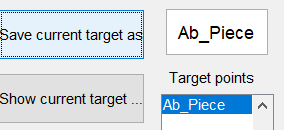

Open fingers

Move robot to grap piece

%simulation_open_tool
%simulation_close_tool
%simulation_grip_piece
%simulation_release_piece

Above box

In box